import robo.*


clearvars ; clc ; close all


Rd = readmatrix("Rd_matrix.csv")

Rd =     0.6691   -0.6798   -0.3002
    0.5736    0.7293   -0.3730
    0.4725    0.0774    0.8779



Rc = readmatrix("Rc_matrix.csv")

Rc =     0.7431   -0.4267   -0.5154
    0.3090    0.9021   -0.3012
    0.5935    0.0646    0.8022



Rb = readmatrix("Rb_matrix.csv")

Rb =     0.6157   -0.6434   -0.4550
    0.4695    0.7632   -0.4440
    0.6329    0.0598    0.7719



checkrotmatrix1 = Rb * Rb' - eye(3)

checkrotmatrix1 = 1.0e-15 *

   -0.6661   -0.0833   -0.2220
   -0.0833   -0.6661    0.0555
   -0.2220    0.0555         0


det(Rb)

ans = 1.0000

checkrotmatrix2 = Rc * Rc' -eye(3)

checkrotmatrix2 = 1.0e-15 *

   -0.1110    0.2220   -0.6661
    0.2220   -0.8882   -0.4996
   -0.6661   -0.4996   -0.7772


det(Rc)

ans = 1.0000

checkrotmatrix3 = Rd * Rc' -eye(3)

checkrotmatrix3 =    -0.0579   -0.3160    0.1124
    0.3073   -0.0525    0.0883
   -0.1344   -0.0486   -0.0103


det(Rd)

ans = 1.0000

% Then we could know Rb,c,d are rotational matrix cause
%==========================

Consider the rotation matrices , and read from the .csv files in the code cell above. Let  R_ab = R_b be the rotation from frame A to frame B, expressed in components in frame A. Let R_c be the rotation from frame B to frame C, expressed in components in frame A. Let R_d be the rotation from frame C to frame D, expressed in components in frame A.

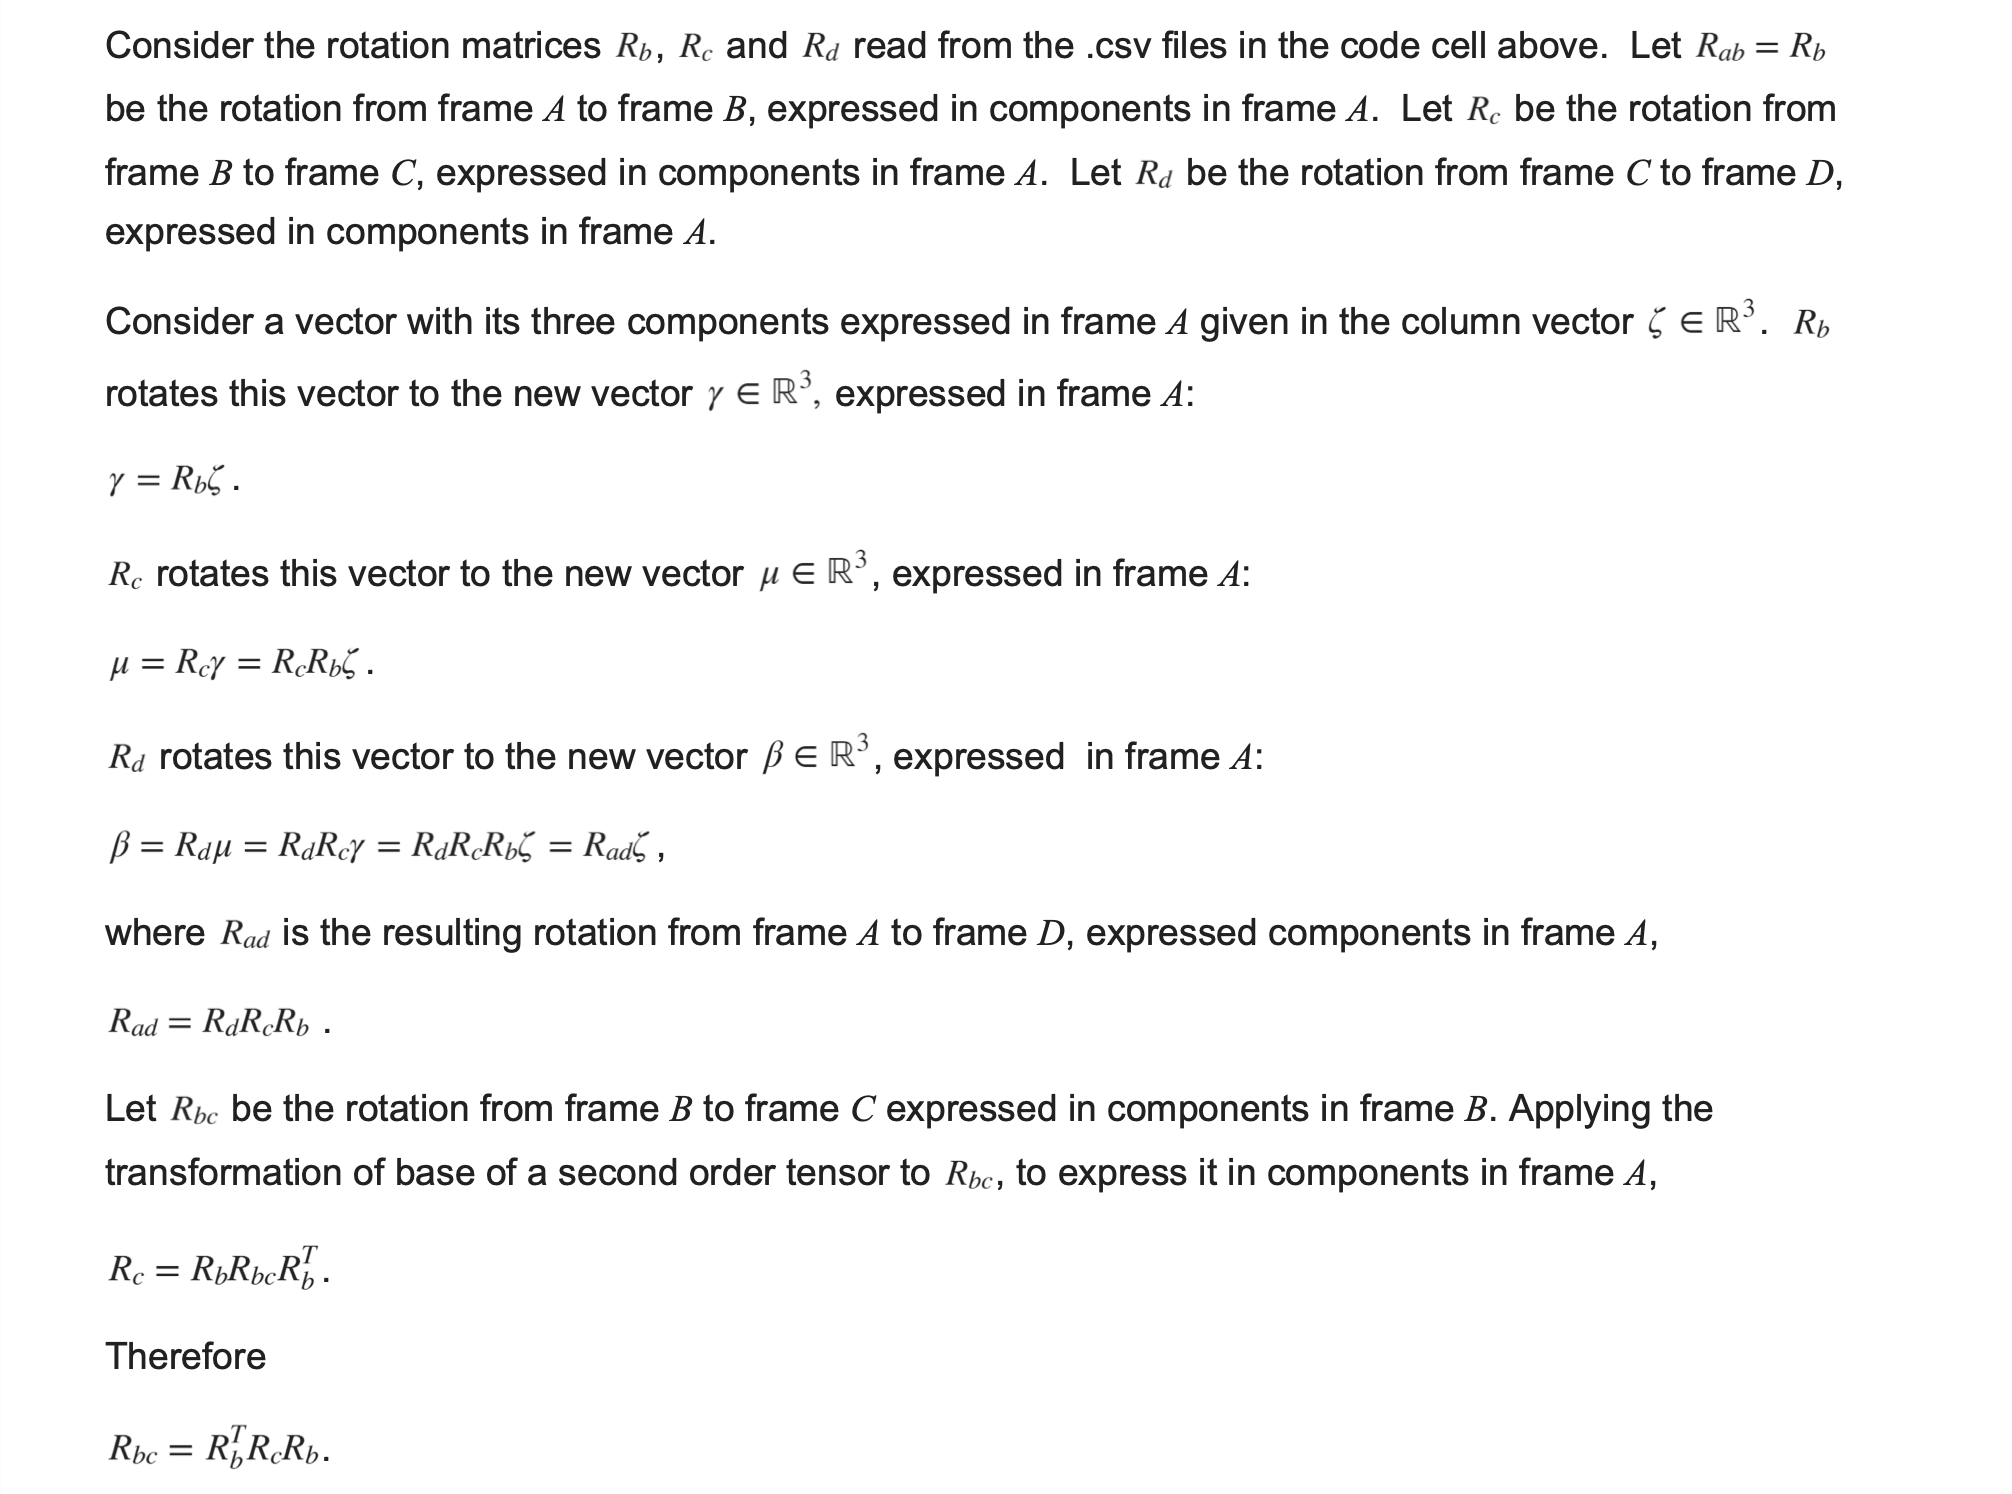

%     let zeta be a three component in given colum vector , Rb rotate
% this component expressed as gammma

zeta  = rand(3,1) % random column vector using 'rand()'

zeta =     0.0357
    0.8491
    0.9340



gamma = Rb* zeta % 3x3 matrix time 3x1 column should be 3*1 column

gamma =    -0.9493
    0.2501
    0.7943



%    Rc rotate vector to new vector should be miu

miu = Rc * gamma 

miu =    -1.2216
   -0.3070
    0.0900




%     Rd totate vector to new vector should be beta

beta = Rd * miu

beta =    -0.6357
   -0.9581
   -0.5220




% Check whether Rad = Rd * Rc * Rb or not

% Rad means rotation from frame A to frame D expressed in frame A

Rad  = Rd * Rc * Rb

Rad =    -0.6051   -0.7936    0.0640
   -0.0680   -0.0286   -0.9973
    0.7933   -0.6078   -0.0367



shouldbezero = Rad*zeta - beta

shouldbezero = 1.0e-15 *

         0
    0.1110
   -0.1110


%then prove it 


%    Let R_c be  the rotation from frame B to frame C expressed in component 
% which in frame B. Applying the transformation of base of a second tensor
% to R_bc to express it in components in frame

% Rc = R_b * Rbc * R_b^T

Rbc_p = Rb'*Rc * Rb; % if not express in frame A then Rbc = Rb' * Rc * Rb

Rc_p = Rb * Rbc_p * Rb'

Rc_p =     0.7431   -0.4267   -0.5154
    0.3090    0.9021   -0.3012
    0.5935    0.0646    0.8022



shouldbezero2  =  Rc_p - Rc

shouldbezero2 = 1.0e-15 *

   -0.8882    0.3886   -0.1110
   -0.3331   -0.9992    0.1110
   -0.5551    0.1804   -0.1110
